clc; clear;

%% ---------- Time & problem size ----------
tf = 3600;    % total time [s]
dt = 600;     % 10 minutes [s]
N  = tf/dt;   % number of intervals -> 6
NX = 4;       % [CA, CB, CC, T]
nu = 2;       % [T0, Tj]

%% ---------- Bounds on controls ----------
lb_value = 273 * ones(N,1);
ub_value = 373 * ones(N,1);

%% ---------- Initial state at t=0 ----------
Y0_INIT = [10; 18; 0; 343 ];   % [ CA, CB, CC, T]

%% ---------- Indexing helpers for z ----------

U0_idx   = @(k) k;                    % T0
Uj_idx   = @(k) N + k;                % Tj
Y_inds   = @(k) (2*N) + (k*NX + (1:NX));  % [CA, CB, CC, T]

%% ---------- Initial guess ----------
U0_init = 343 * ones(N,1);
Uj_init = 343 * ones(N,1);

% y_nodes_guess = zeros((N+1)*NX, 1);
% y_nodes_guess(Y_inds(0)) = Y0_INIT;
y_nodes_guess = repmat(Y0_INIT, N+1, 1);

% forward simulate with initial controls to seed node guesses
% Yk = Y0_INIT;
% for k = 1:N
%      uk = [U0_init(k); Uj_init(k)];
%      Yk1 = integrate_interval(Yk, uk, dt);     % uses daeSystemLHS(t,y,PARAMS)
%      y_nodes_guess(Y_inds(k)) = Yk1;
%      Yk = Yk1;
%  end

z0 = [U0_init; Uj_init; y_nodes_guess];

%% ---------- Variable bounds ----------
lb = -inf(size(z0));
ub =  inf(size(z0));
% control bounds
for k = 1:N
    lb(U0_idx(k)) = lb_value(k);
    ub(U0_idx(k)) = ub_value(k);
    lb(Uj_idx(k)) = lb_value(k);
    ub(Uj_idx(k)) = ub_value(k);
end
% Y nodes left unbounded (constrained by equality conditions)

%% ---------- Objective: maximize CA(tf) -> minimize -CA(tf) ----------
% final node indices:
finalY_inds = Y_inds(N);       % [CA, CB, CC, T] at final node
finalCA_idx = finalY_inds(1);  % CA component index
objFun = @(z) -z(finalCA_idx);

%% ---------- Nonlinear constraints (continuity + rate limits + initial node) ----------
nonlcon = @(z) multipleShootingConstraints(z, U0_idx, Uj_idx, Y_inds, N, NX, Y0_INIT, dt);

%% ---------- Solve ----------
opts = optimoptions('fmincon', ...
    'Display','iter', ...
    'Algorithm','interior-point', ...
    'MaxFunctionEvaluations', 2e5, ...
    'MaxIterations', 2000, ...
    'ConstraintTolerance', 1e-8, ...
    'OptimalityTolerance', 1e-6, ...
    'StepTolerance', 1e-10);

z_opt = fmincon(objFun, z0, [], [], [], [], lb, ub, nonlcon, opts);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      41   -1.000000e+01    3.095e+00    1.734e-01
    1      83   -4.326623e+00    2.994e+00    3.256e-01    4.129e+01
    2     124   -6.770872e+00    4.007e-02    3.692e-01    7.458e+00
    3     165   -6.745671e+00    3.845e-06    4.205e-02    1.042e-01
    4     206   -6.752617e+00    5.175e-06    1.385e-01    9.967e-02
    5     247   -6.787359e+00    1.304e-04    2.097e-01    4.979e-01
    6     288   -6.954888e+00    3.100e-03    2.393e-01    2.384e+00
    7     329   -7.185655e+00    7.854e-03    4.185e-02    3.167e+00
    8     370   -7.154425e+00    1.556e-04    5.006e-01    5.112e-01
    9     411   -7.313125e+00    2.824e-03    2.108e-01    2.273e+00
   10     453   -7.351203e+00    2.386e-03    2.071e-01    5.531e-01
   11     494   -7.467123e+00    2.127e-03    1.729e-01    1.801e+00
   12     535   -7.758454e+00    1.748e-02    1

result:

%% ---------- Unpack results ----------
U0_opt = z_opt( U0_idx(1):U0_idx(N) );
Uj_opt = z_opt( Uj_idx(1):Uj_idx(N) );

fprintf('\nOptimal controls per 10 min (T0, Tj):\n');


Optimal controls per 10 min (T0, Tj):


for k = 1:N
    fprintf('  Interval %d: T0 = %.3f K,  Tj = %.3f K\n', k, U0_opt(k), Uj_opt(k));
end

  Interval 1: T0 = 319.567 K,  Tj = 317.798 K
  Interval 2: T0 = 324.567 K,  Tj = 322.798 K
  Interval 3: T0 = 329.567 K,  Tj = 327.798 K
  Interval 4: T0 = 334.567 K,  Tj = 332.798 K
  Interval 5: T0 = 339.567 K,  Tj = 337.798 K
  Interval 6: T0 = 344.567 K,  Tj = 342.798 K



Y_nodes_opt = z_opt( 2*N + (1:(N+1)*NX) );
CA_end = Y_nodes_opt( (N*NX) + 1 );
fprintf('Final CA = %.6f mol/m^3\n', CA_end);

Final CA = 9.925513 mol/m^3


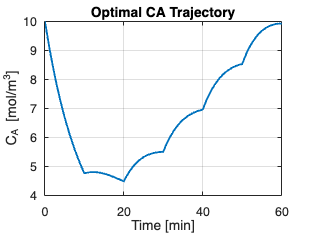


%% ---------- Re-simulate full trajectory with optimal controls ----------
[t_all, Y_all] = simulate_trajectory(Y0_INIT, U0_opt, Uj_opt, dt);

% Plots
figure; plot(t_all/60, Y_all(:,1), 'LineWidth', 1.5); grid on;
xlabel('Time [min]'); ylabel('C_A [mol/m^3]'); title('Optimal CA Trajectory');

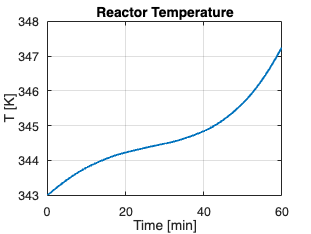


figure; plot(t_all/60, Y_all(:,4), 'LineWidth', 1.5); grid on;
xlabel('Time [min]'); ylabel('T [K]'); title('Reactor Temperature');

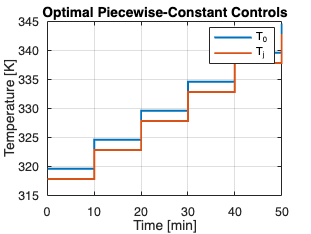


figure; stairs((0:N-1)*dt/60, U0_opt, 'LineWidth', 1.5); grid on; hold on;
stairs((0:N-1)*dt/60, Uj_opt, 'LineWidth', 1.5);
xlabel('Time [min]'); ylabel('Temperature [K]');
legend('T_0','T_j'); title('Optimal Piecewise-Constant Controls');